# Pointclouds

## Creating a pointcloud object

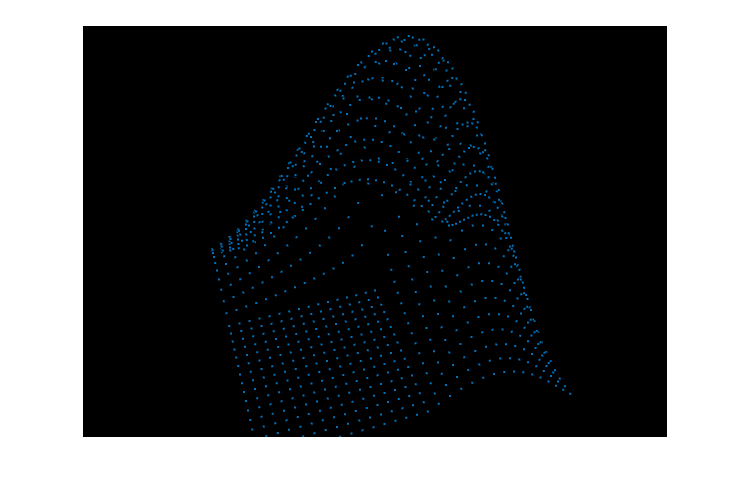

% create a pointcloud from the membrane function
f = fvclear;
Z = membrane(1).*25;
sz = size(Z);
[X,Y] = ndgrid(1:sz(1),1:sz(2));
coordinates = [X(:) Y(:) Z(:)];

pc = fvPointcloud(coordinates);
f.Camera.Rotation = [-46.8000         0  -72.0000];
f.Snapshot;

## Colorize each points with a colormap depending on their Z value

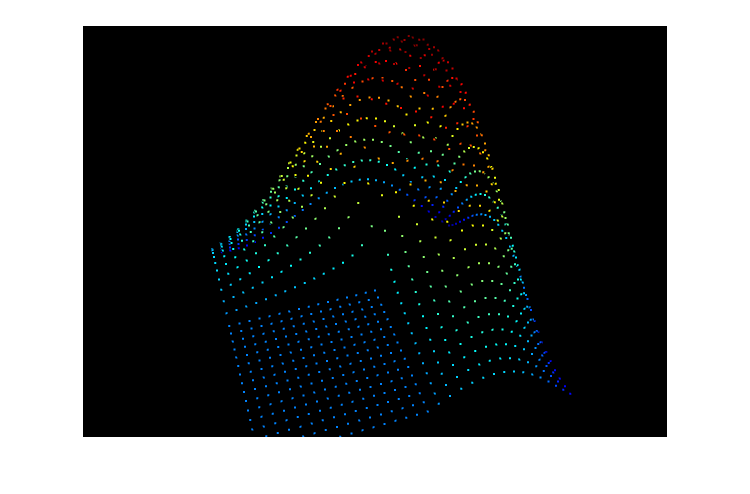

pc.Color = rescale(pc.Coord(:,3));
pc.Colormap = 'jet';
f.Snapshot;

## Setting the point size and making points circular

Points will be fixed to a diameter of 6 pixels

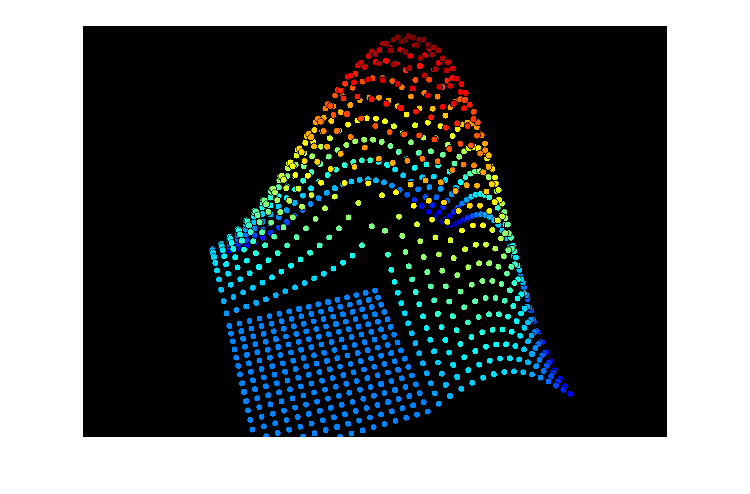

pc.PointSize = 6;
pc.PointShape = 'round';
f.Snapshot;

## Set the point sizes in world unit

Points have a fixed size of 0.5 world unit diameter

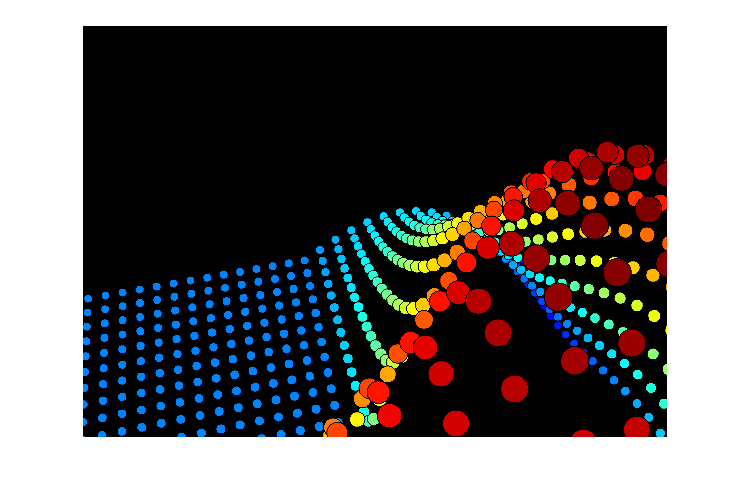

pc.PointUnit = 'world';
pc.PointSize = 0.5;

% Move camera closer to see the size difference
f.Camera.Origin = [18.7613 2.3274 8.0738];
f.Camera.Rotation = [-40.4000 0 -167.2000];
f.Camera.Translation = [-6.7525 1.9845 -36.3372];
f.Snapshot;

## Set the point shape to a cross

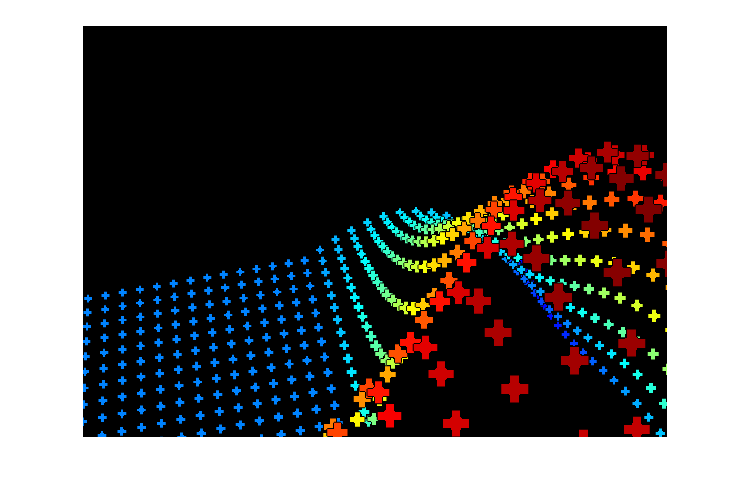

pc.PointShape = [0 0 1 1 0 0
                 0 0 1 1 0 0
                 1 1 1 1 1 1
                 1 1 1 1 1 1
                 0 0 1 1 0 0
                 0 0 1 1 0 0];
f.Snapshot;